data=readtable('P4_data.xlsx');
P4data=table2array(data(1:end,4:13));
iGroup1nosmoke = readtable('Group1_nosmoke.xlsx');

iGroup1smoke = readtable('Group1_smoke.xlsx');

iGroup2nosmoke = readtable('Group2_nosmoke.xlsx');

iGroup2smoke = readtable('Group2_smoke.xlsx');

iGroup3nosmoke = readtable('Group3_nosmoke.xlsx');

iGroup3smoke = readtable('Group3_smoke.xlsx');

Group1nosmoke = table2array(iGroup1nosmoke);
Group1smoke = table2array(iGroup1smoke);
Group2nosmoke = table2array(iGroup2nosmoke);
Group2smoke = table2array(iGroup2smoke);
Group3nosmoke = table2array(iGroup3nosmoke);
Group3smoke = table2array(iGroup3smoke);


Group1nosmoke(13:24,:) = 6 - Group1nosmoke(13:24,:);
Group1smoke(13:24,:) = 6 - Group1smoke(13:24,:);

Group2nosmoke(1:12,:) = 6 - Group2nosmoke(1:12,:);
Group2smoke(1:12,:) = 6 - Group2smoke(1:12,:);


Group3nosmoke(13:24,:) = 6 - Group3nosmoke(13:24,:);
Group3smoke(13:24,:) = 6 - Group3smoke(13:24,:);

negatives=[2 3 7 8];
P4data(:,negatives)=6-P4data(:,negatives);
P4data=P4data(:,[1 2 3 4 5 6 8 9 10]);
grp1 = P4data(:,[1 2 6]);
grp2 = P4data(:,[3 5 8]);
grp3 = P4data(:,[4 7 9]);


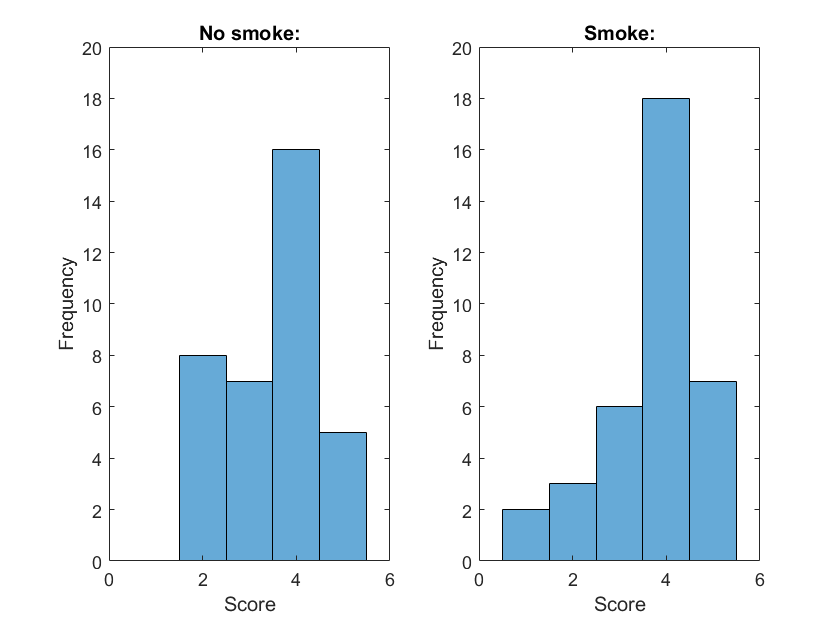


figure
subplot(1,2,1)
title('Sound grouped answers:')
histogram(grp1(1:12,:))
xlim([0 6])
ylim([0 20])
title('No smoke:')
xlabel('Score')
ylabel('Frequency')
subplot(1,2,2)
histogram(grp1(13:24,:))
xlim([0 6])
ylim([0 20])
title('Smoke:')
xlabel('Score')
ylabel('Frequency')

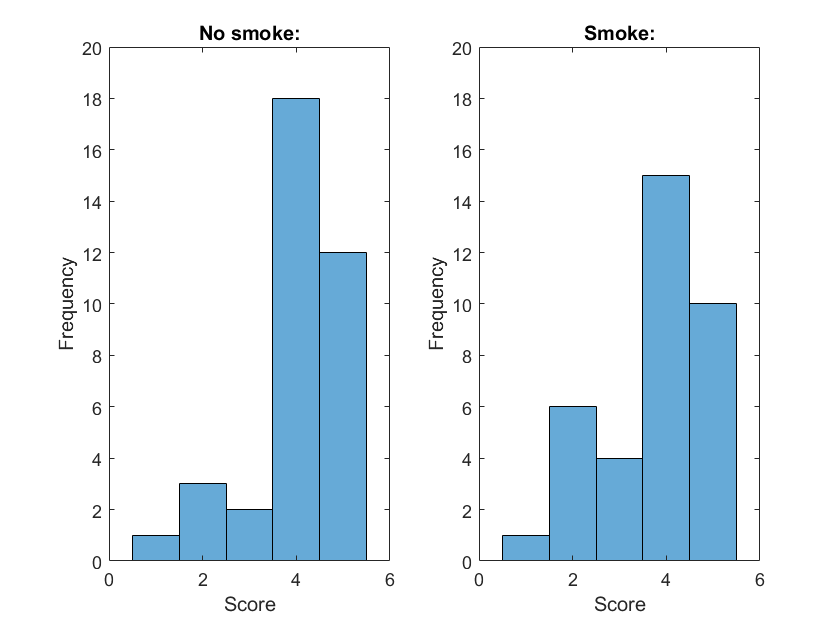

figure
subplot(1,2,1)
title('Interaction grouped answers:')
histogram(grp2(1:12,:))
xlim([0 6])
ylim([0 20])
title('No smoke:')
xlabel('Score')
ylabel('Frequency')
subplot(1,2,2)
histogram(grp2(13:24,:))
xlim([0 6])
ylim([0 20])
title('Smoke:')
xlabel('Score')
ylabel('Frequency')

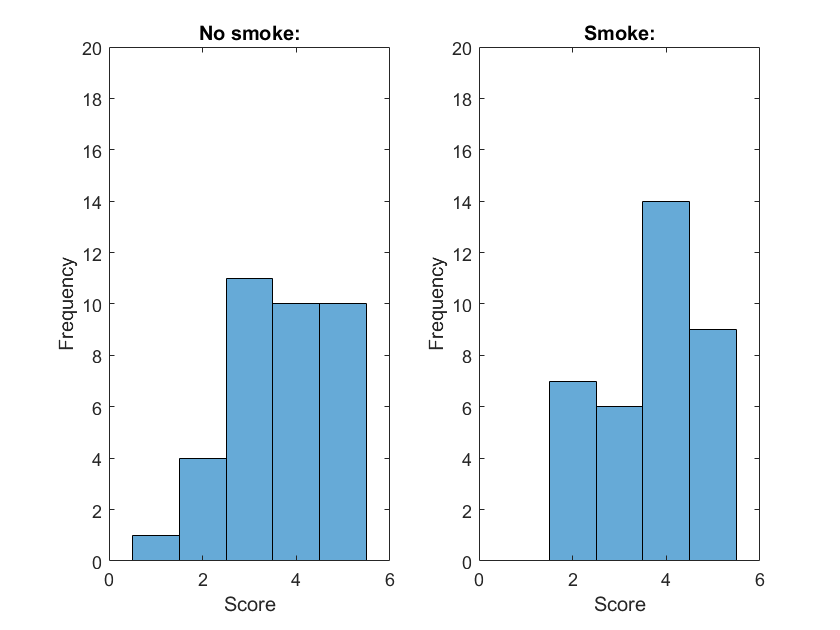

figure
subplot(1,2,1)
title('Performance grouped answers:')
histogram(grp3(1:12,:))
xlim([0 6])
ylim([0 20])
title('No smoke:')
xlabel('Score')
ylabel('Frequency')
subplot(1,2,2)
histogram(grp3(13:24,:))
xlim([0 6])
ylim([0 20])
title('Smoke:')
xlabel('Score')
ylabel('Frequency')

mnsg1=mean2(grp1(1:12,:))

mnsg1 = 3.5000

msg1=mean2(grp1(13:24,:))

msg1 = 3.6944

snsg1=std2(grp1(1:12,:))

snsg1 = 1

ssg1=std2(grp1(13:24,:))

ssg1 = 1.0642

mnsg2=mean2(grp2(1:12,:))

mnsg2 = 4.0278

msg2=mean2(grp2(13:24,:))

msg2 = 3.7500

snsg2=std2(grp2(1:12,:))

snsg2 = 0.9996

ssg2=std2(grp2(13:24,:))

ssg2 = 1.1307

mnsg3=mean2(grp3(1:12,:))

mnsg3 = 3.6667

msg3=mean2(grp3(13:24,:))

msg3 = 3.6944

snsg3=std2(grp3(1:12,:))

snsg3 = 1.0954

ssg3=std2(grp3(13:24,:))

ssg3 = 1.0642

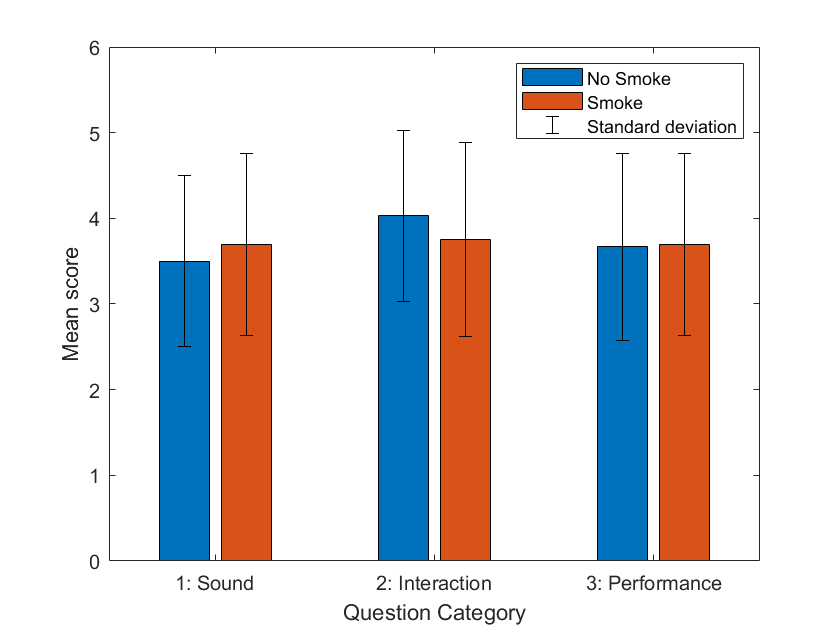

data1 = [mnsg1,msg1];
data2 = [mnsg2,msg2];
data3 = [mnsg3,msg3];
y=[data1;data2;data3];
err=[snsg1,ssg1;snsg2,ssg2;snsg3,ssg3];
figure
c = categorical({'1: Sound','2: Interaction','3: Performance'});
bar(y,'grouped')
set(gca, 'XTickLabel', {'1: Sound','2: Interaction','3: Performance'});
hold on
ngroups = size(y, 1);
nbars = size(y, 2);
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er=errorbar(x, y(:,i), err(:,i));
    er.Color = [0 0 0];                            
er.LineStyle = 'none';  
end
legend('No Smoke','Smoke','Standard deviation')
ylabel('Mean score')
xlabel('Question Category')
hold off

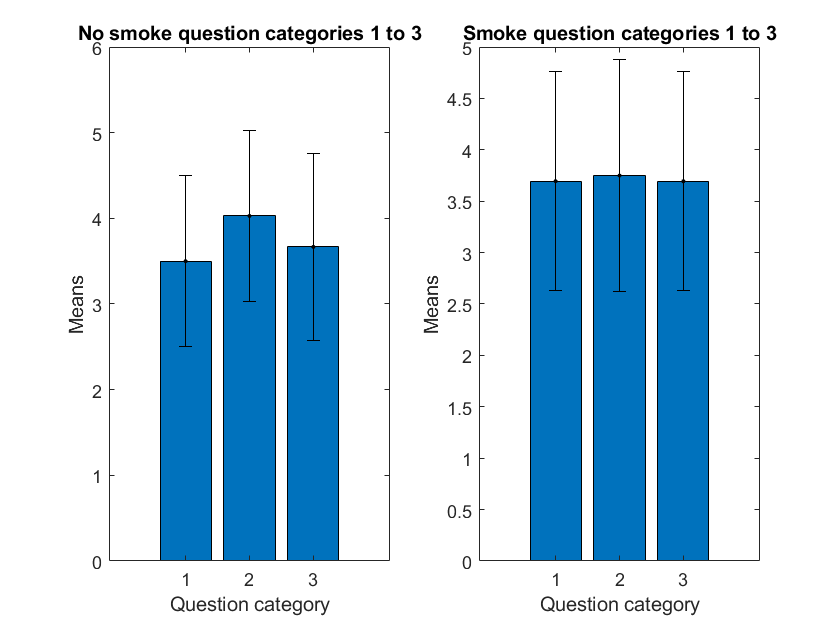

means=[mean2(grp1(1:12,:)); mean2(grp2(1:12,:));mean2(grp3(1:12,:))];
%calculate stdev
sd=[std2(grp1(1:12,:)); std2(grp2(1:12,:));std2(grp3(1:12,:))];
meansS=[mean2(grp1(13:24,:)); mean2(grp2(13:24,:));mean2(grp3(13:24,:))];
%calculate stdev
sdS=[std2(grp1(13:24,:)); std2(grp2(13:24,:));std2(grp3(13:24,:))];

figure
subplot(1,2,1)
bar(means)
title('No smoke question categories 1 to 3')
ylabel('Means')
xlabel('Question category')
hold on
errorbar(means,sd,'.k')
subplot(1,2,2)
bar(meansS)
title('Smoke question categories 1 to 3')
ylabel('Means')
xlabel('Question category')
hold on
errorbar(meansS,sdS,'.k')

G=Group1nosmoke.^2;
[transdat,lambda] = boxcox(Group1nosmoke);
[transdat1,lambda1] = boxcox(G);
[h,p,adstat,cv] = adtest(transdat)

h = logical
   1


p = 5.0000e-04

adstat = 2.1375

cv = 0.7351

[h,p,adstat,cv] = adtest(transdat1)

h = logical
   1


p = 5.0000e-04

adstat = 2.1375

cv = 0.7351

[h,p,adstat,cv] = adtest(Group1nosmoke)

h = logical
   1


p = 5.0000e-04

adstat = 2.2219

cv = 0.7351

[h,p,adstat,cv] = adtest(Group1smoke)

h = logical
   1


p = 5.0000e-04

adstat = 2.4418

cv = 0.7351


[h,p,adstat,cv] = adtest(Group2nosmoke)

h = logical
   1


p = 5.0000e-04

adstat = 3.1705

cv = 0.7351

[h,p,adstat,cv] = adtest(Group2smoke)

h = logical
   1


p = 5.0000e-04

adstat = 2.2258

cv = 0.7351


[h,p,adstat,cv] = adtest(Group3nosmoke)

h = logical
   1


p = 5.0000e-04

adstat = 1.5379

cv = 0.7351

[h,p,adstat,cv] = adtest(Group3smoke)

h = logical
   1


p = 5.0000e-04

adstat = 1.9872

cv = 0.7351

Group2nosmoke(1:12,:)

ans =      2
     4
     4
     5
     3
     4
     4
     4
     4
     4


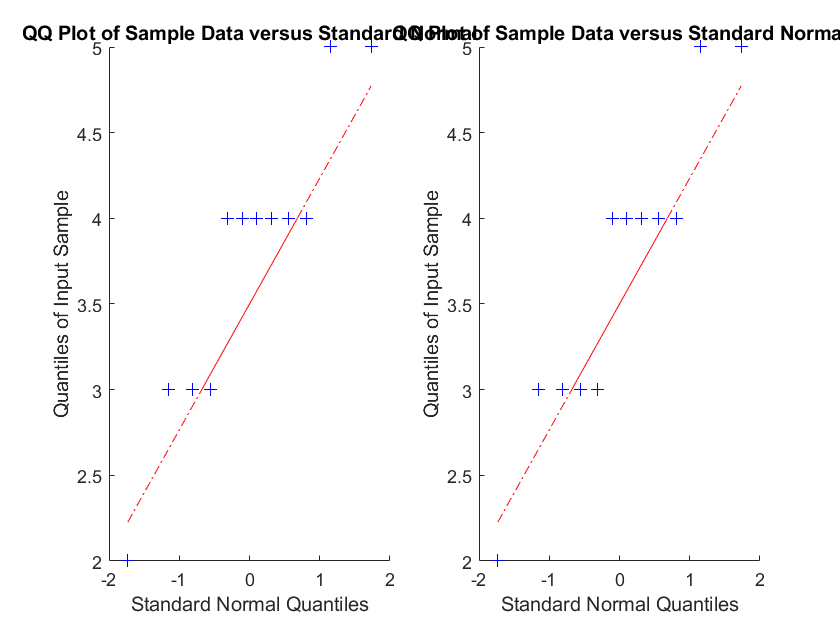

figure
subplot(1,2,1)
qqplot(Group1nosmoke(1:12,:))
subplot(1,2,2)
qqplot(Group1smoke(1:12,:))

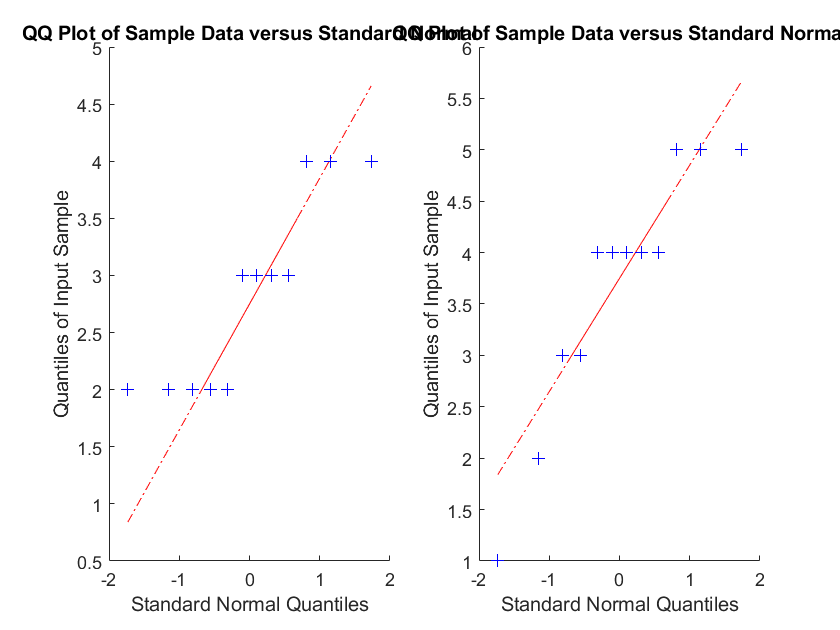

figure
subplot(1,2,1)
qqplot(Group1nosmoke(13:24,:))
subplot(1,2,2)
qqplot(Group1smoke(13:24,:))

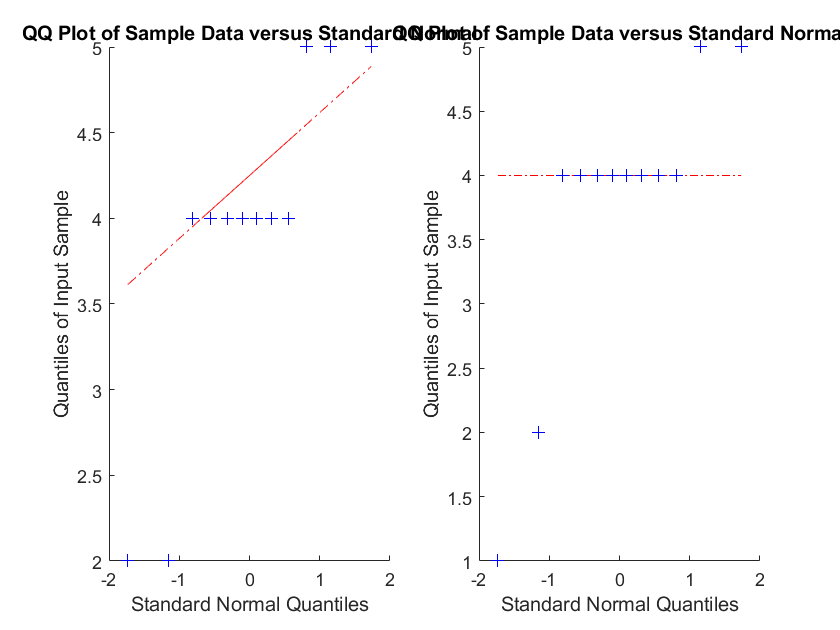

figure
subplot(1,2,1)
qqplot(Group1nosmoke(25:36,:))
subplot(1,2,2)
qqplot(Group1smoke(25:36,:))

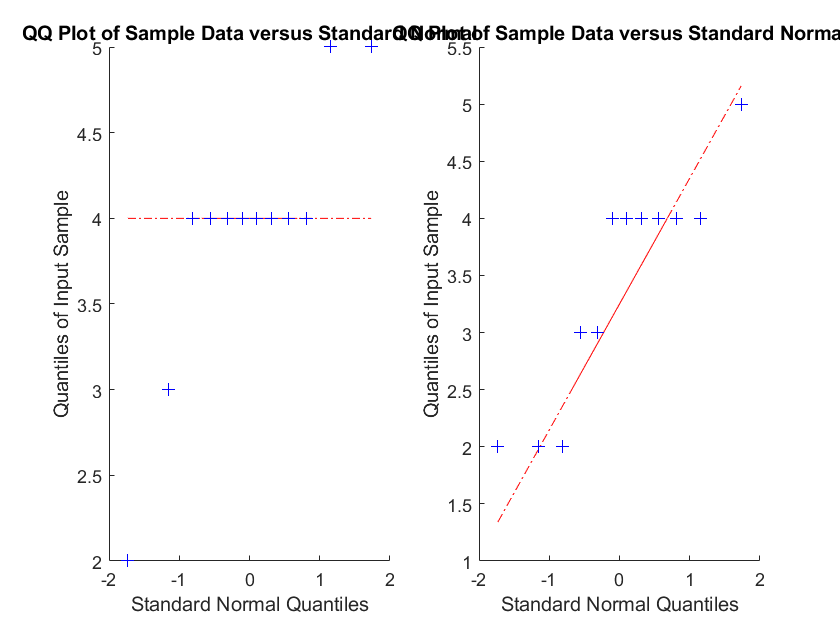

figure
subplot(1,2,1)
qqplot(Group2nosmoke(1:12,:))
subplot(1,2,2)
qqplot(Group2smoke(1:12,:))

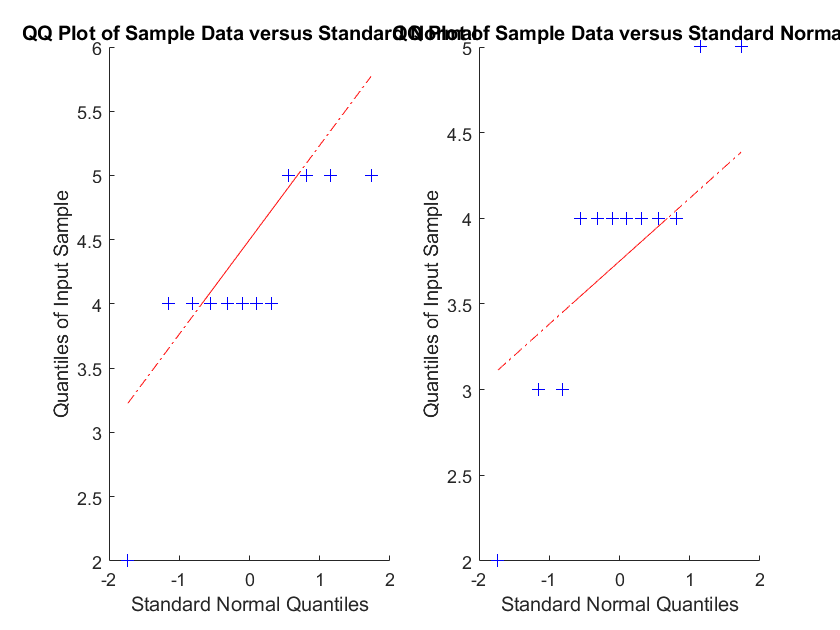

figure
subplot(1,2,1)
qqplot(Group2nosmoke(13:24,:))
subplot(1,2,2)
qqplot(Group2smoke(13:24,:))

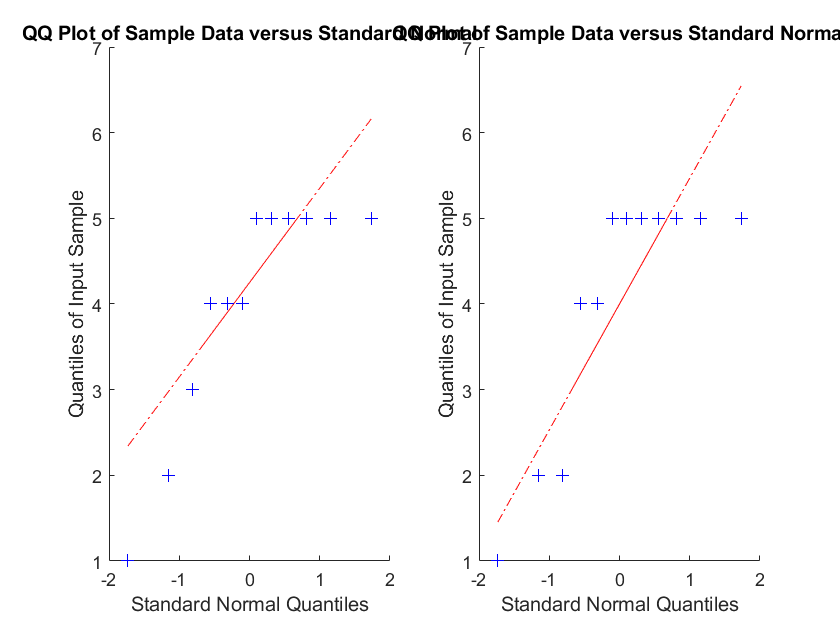

figure
subplot(1,2,1)
qqplot(Group2nosmoke(25:36,:))
subplot(1,2,2)
qqplot(Group2smoke(25:36,:))

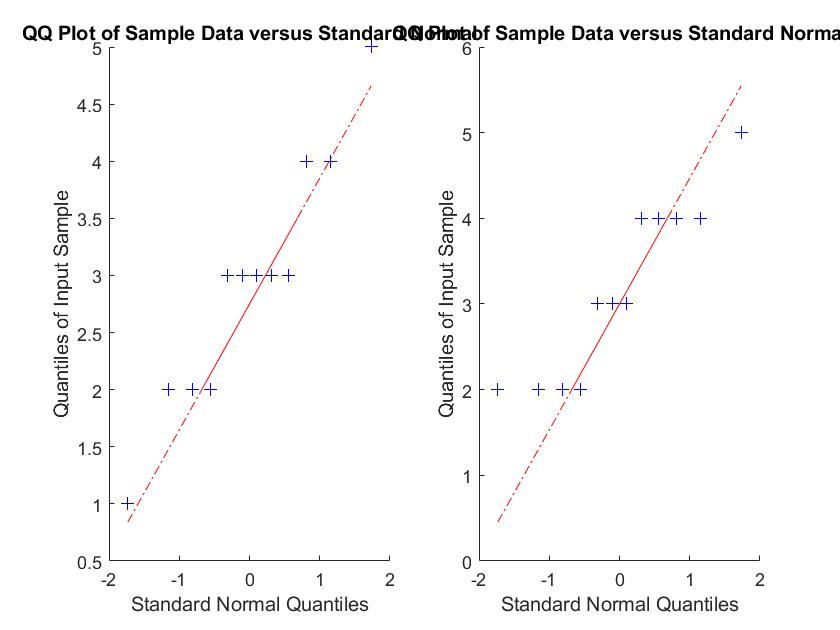

figure
subplot(1,2,1)
qqplot(Group3nosmoke(1:12,:))
subplot(1,2,2)
qqplot(Group3smoke(1:12,:))

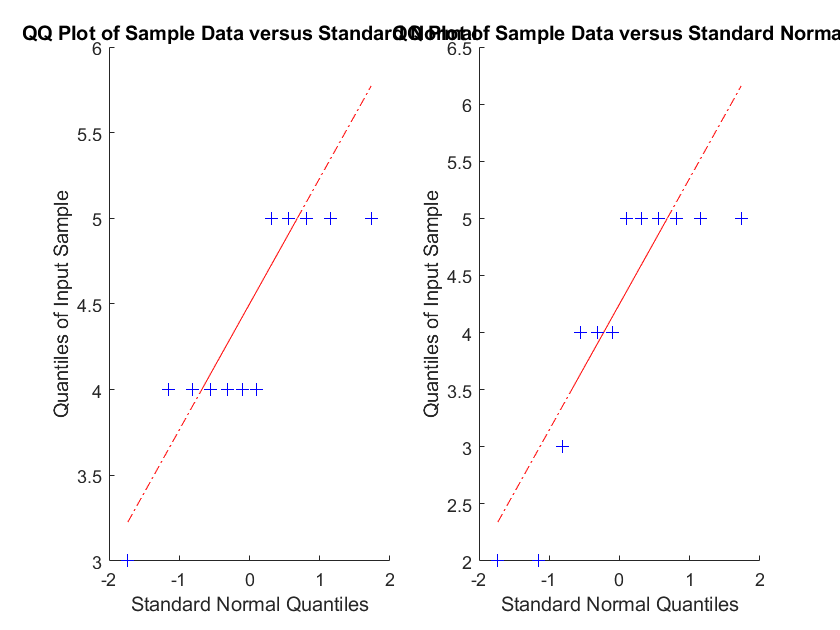

figure
subplot(1,2,1)
qqplot(Group3nosmoke(13:24,:))
subplot(1,2,2)
qqplot(Group3smoke(13:24,:))

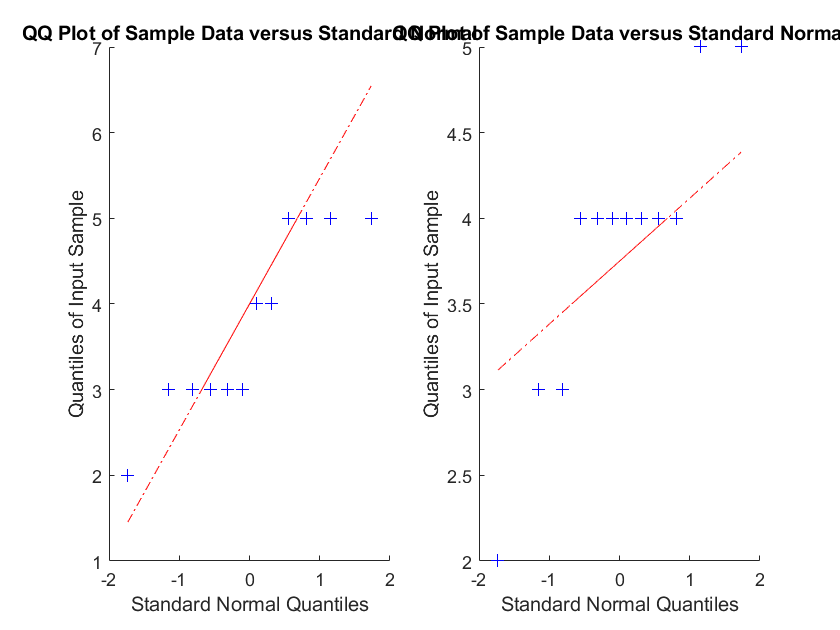

figure
subplot(1,2,1)
qqplot(Group3nosmoke(25:36,:))
subplot(1,2,2)
qqplot(Group3smoke(25:36,:))

[p,h, stats] = ranksum(Group1nosmoke, Group1smoke)

p = 0.3310

h = logical
   0


stats = struct with fields:
       zval: -0.9720
    ranksum: 1.2325e+03


[p,h, stats] = ranksum(Group2nosmoke, Group2smoke)

p = 0.2943

h = logical
   0


stats = struct with fields:
       zval: 1.0488
    ranksum: 1.4015e+03


[p,h, stats] = ranksum(Group3nosmoke, Group3smoke)

p = 0.9208

h = logical
   0


stats = struct with fields:
       zval: -0.0994
    ranksum: 1305


noSmoke=[Group1nosmoke; Group2nosmoke; Group3nosmoke];
Smoke=[Group1smoke; Group2smoke; Group3smoke];
[p,h, stats] = ranksum(noSmoke, Smoke)

p = 0.9735

h = logical
   0


stats = struct with fields:
       zval: 0.0332
    ranksum: 11733


Comlang=0.0332/144

Comlang = 2.3056e-04

[h,p ]= ttest2(Group1nosmoke,Group1smoke,'Vartype','unequal')

h = 0

p = 0.4271

[h,p ]= ttest2(Group1nosmoke(1:12,:),Group1smoke(1:12,:),'Vartype','unequal')

h = 0

p = 0.8181

[h,p ]= ttest2(Group1nosmoke(13:24,:),Group1smoke(13:24,:),'Vartype','unequal')

h = 0

p = 0.0670

[h,p ]= ttest2(Group1nosmoke(25:36,:),Group1smoke(25:36,:),'Vartype','unequal')

h = 0

p = 0.7064

[h,p ]= ttest2(Group2nosmoke,Group2smoke,'Vartype','unequal')

h = 0

p = 0.2733

[h,p ]= ttest2(Group2nosmoke(1:12,:),Group2smoke(1:12,:),'Vartype','unequal')

h = 0

p = 0.1882

[h,p ]= ttest2(Group2nosmoke(13:24,:),Group2smoke(13:24,:),'Vartype','unequal')

h = 0

p = 0.3387

[h,p ]= ttest2(Group2nosmoke(25:36,:),Group2smoke(25:36,:),'Vartype','unequal')

h = 0

p = 1

[h,p ]= ttest2(Group3nosmoke,Group3smoke,'Vartype','unequal')

h = 0

p = 0.9134

[h,p ]= ttest2(Group3nosmoke(1:12,:),Group3smoke(1:12,:),'Vartype','unequal')

h = 0

p = 0.5683

[h,p ]= ttest2(Group3nosmoke(13:24,:),Group3smoke(13:24,:),'Vartype','unequal')

h = 0

p = 0.5248

[h,p ]= ttest2(Group3nosmoke(25:36,:),Group3smoke(25:36,:),'Vartype','unequal')

h = 0

p = 0.8322

[h,p ]= ttest2(P4data(1:12,:),P4data(13:24,:),'Vartype','unequal')

h =      0     0     0     0     0     0     0     0     0


p =     0.8181    0.0670    0.1882    0.5683    0.3387    0.7064    0.5248    1.0000    0.8322


cronbach(P4data)

ans = 0.7164

d=(mean2(P4data(1:12,:))-mean2(P4data(13:24,:)))/std2(P4data)

d = 0.0175


sterr=std2( P4data ) / sqrt( length( P4data ))

sterr = 0.2163

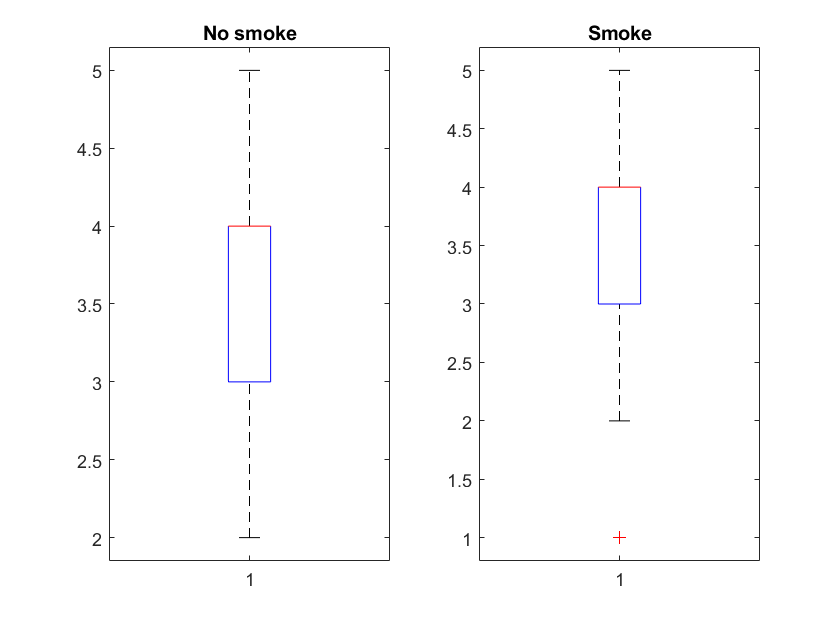

figure
subplot(1,2,1)
boxplot(Group1nosmoke)
title('No smoke')
subplot(1,2,2)
boxplot(Group1smoke)
title('Smoke')

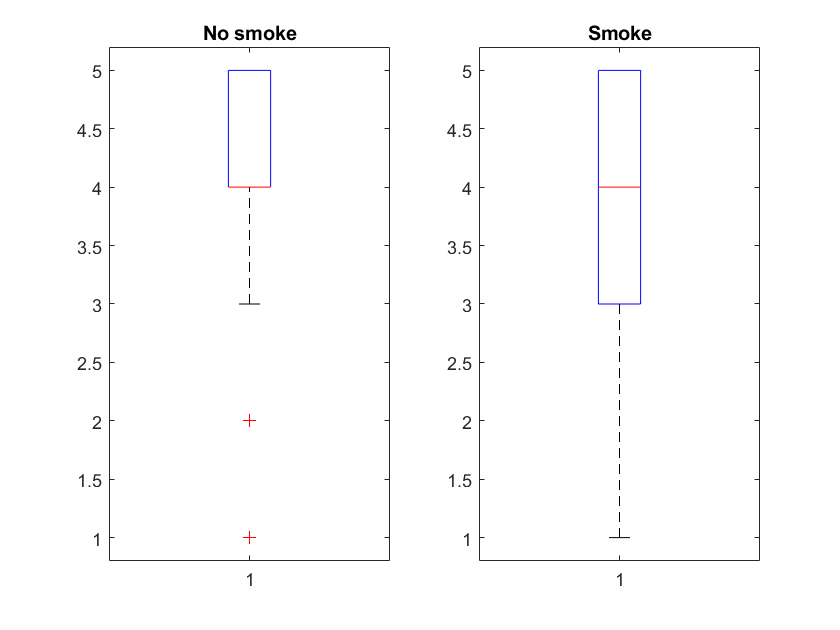

figure
subplot(1,2,1)
boxplot(Group2nosmoke)
title('No smoke')
subplot(1,2,2)
boxplot(Group2smoke)
title('Smoke')

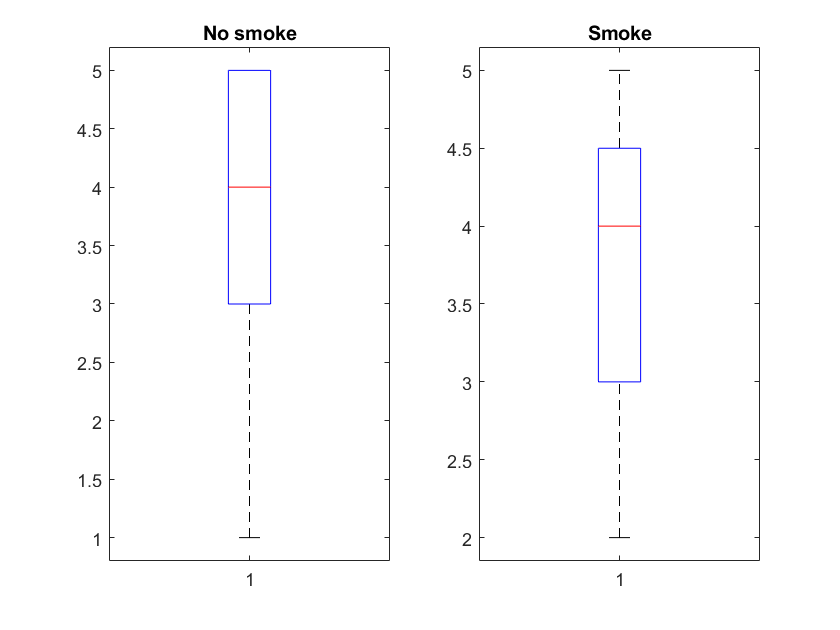

figure
subplot(1,2,1)
boxplot(Group3nosmoke)
title('No smoke')
subplot(1,2,2)
boxplot(Group3smoke)
title('Smoke')

function a=cronbach(X)
%Syntax: a=cronbach(X)
%_____________________
%
% Calculates the Cronbach's alpha of a data set X.
%
% a is the Cronbach's alpha.
% X is the data set.
%
%
% Reference:
% Cronbach L J (1951): Coefficient alpha and the internal structure of
% tests. Psychometrika 16:297-333
%
%
% Alexandros Leontitsis
% Department of Education
% University of Ioannina
% Ioannina
% Greece
%
% e-mail: leoaleq@yahoo.com
% Homepage: http://www.geocities.com/CapeCanaveral/Lab/1421
%
% June 10, 2005.


if nargin<1 | isempty(X)==1
   error('You shoud provide a data set.');
else
   % X must be a 2 dimensional matrix
   if ndims(X)~=2
      error('Invalid data set.');
   end
end


% Calculate the number of items
k=size(X,2);

% Calculate the variance of the items' sum
VarTotal=var(sum(X'));

% Calculate the item variance
SumVarX=sum(var(X));

% Calculate the Cronbach's alpha
a=k/(k-1)*(VarTotal-SumVarX)/VarTotal;
end